# **Solar Cooker Model**

**Jacob Smilg & Daniel Park**

## **Question:**

**Design - What type of pot material and mirror diameter should we design our solar cooker in order to raise the temperature of two liters of water from 20°C to 100°C in under 5 minutes?**

This is a design question because we are trying to find particular parameters of a solar cooker that accomplish a specific goal. Asking this question could be useful to finding an optimal solar cooker design, which would be useful for people who live in areas such as the Himalayas where there is limited access to traditional fuels. The question is interesting because it has the potential to result in a design that isn't feasible to construct or use.

## **Methodology/Model:**

To answer our question, we will construct a stock and flow model based on three mechanisms of energy transfer in order to determine the material of the pot and diameter of the parabolic mirrors for a solar cooker that would accomplish the goal laid out in the question.

**Stock and Flow Diagram:**

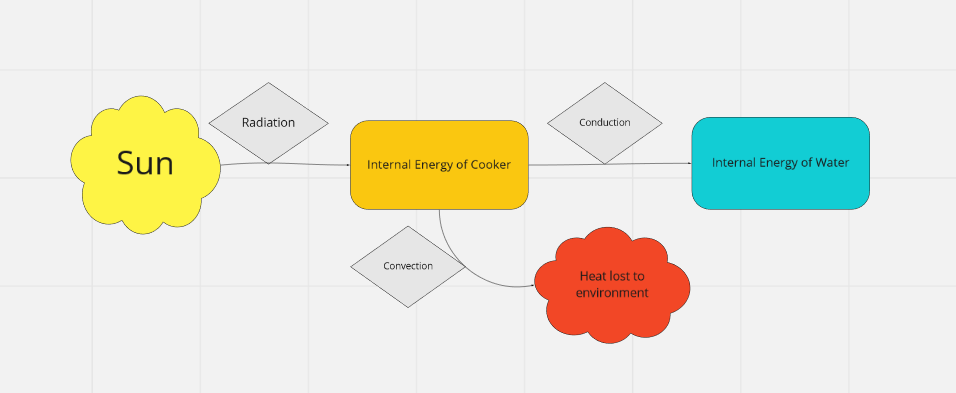

**Schematic & Photo:**

The diagram and photo below represent what our theoretical solar cooker model would look like

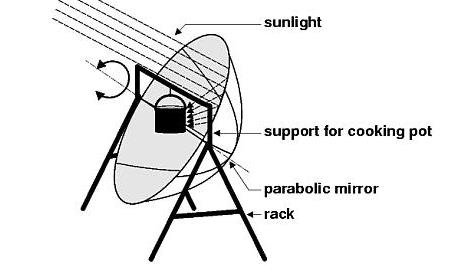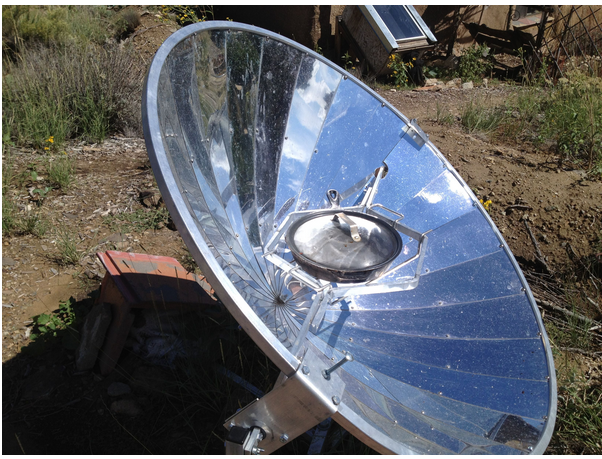

**Stocks:**

- Sun (Source)

- Internal Energy of the Cooker

- Internal Energy of the Water

**Flows:**

- Radiation (from Sun --> Cooker)

- Conduction (from Cooker --> Water)

- Convection (from Cooker --> Air)

**Equations:**

- $\frac{\textrm{dU}}{\;\textrm{dt}}=\textrm{elA}$ *(flow of radiation from sun to the cooker)*

- $\frac{\textrm{dQ}}{\textrm{dt}}=-\frac{\textrm{kA}}{d\Delta T}$ *(flow of conduction from cooker to the water)*

- $\frac{\textrm{dQ}}{\textrm{dt}}=\textrm{hA}\left(T_{\textrm{air}} -T_{\textrm{cooker}} \right)$ (*flow of convection from cooker to the air)*

**Assumptions and Abstractions:**

- This solar cooker will opeate in the Himalayas (28 degrees Latitude) on January 1 at solar noon 

- The mirrors will transfer all energy, instead of some energy lost, it receives from the sun to the cooker 

- We are assuming the dimensions of the pot to hold about 2L of water. (14 cm tall x 14 cm diameter, 0.5 cm thickness, actual volume = 2.155 L)

- We are assuming the pot has a lid because boiling water without a lid causes heat loss through evaporation and convection between the surrounding air and the water.

- We assumed that the pot will be cooking at the highest wind speeds at all times (Convection Coefficient static on 25 W/m^2*K)

- Insolation is 1000 W/m^2 for noon at sea level until we know the insolation for the Himalayas later <- need to change

**Development and Refinement:**

- What additional representations of your model would help?

- How did you set parameters?

- How did you verify model?

- What plan would you use to validate model?

## **Results:**

**Material Sweep:**

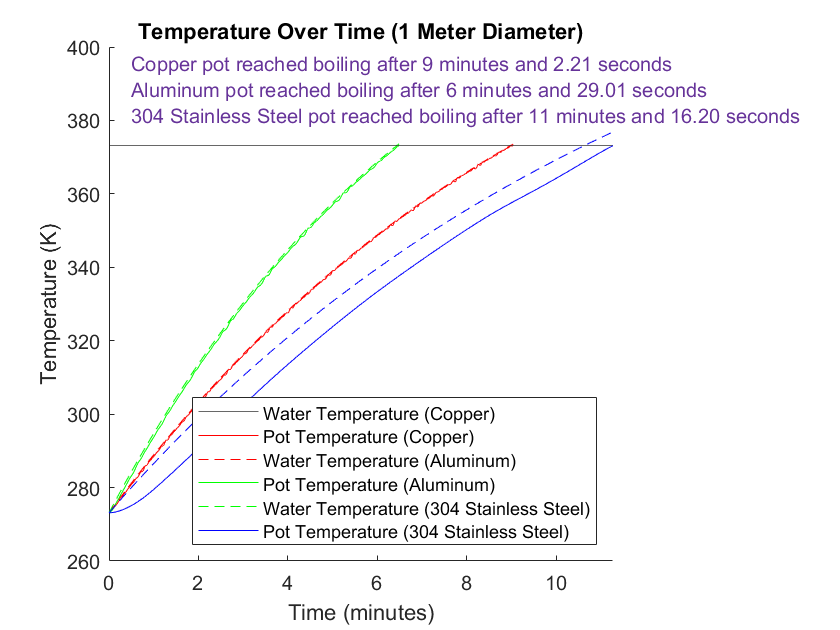

materials = ["Copper", "Aluminum", "304 Stainless Steel"];
figure(); 
hold on

yline(373.15); % Boiling temperature in K
xlabel('Time (minutes)');
ylabel('Temperature (K)');
title(sprintf('Temperature Over Time (1 Meter Diameter)'))
colors = {'r','r','g','g','b','b'};
colororder(colors);

a = gca;
a.Position(3) = 0.6;
boilTime = "";

for i = 1:length(materials)
    [T, waterTemp, potTemp, endTime] = single_diameter_v2(materials(i), 1);
    [endMinute, endSecond] = minutesToMinutesSeconds(endTime);
    plot(T, waterTemp, '-', T, potTemp,'--');
    xlim([0 endTime])
    ylim([260 400])
    
    boilTime = boilTime + sprintf("%s pot reached boiling after %i minutes and %.2f seconds \n", materials(i), endMinute, endSecond);
    %text(endTime-.1, 377, txt, 'HorizontalAlignment', 'right') % what does this do?
end

%annotation('textbox', [0.15, 0.825, 0.1, 0.1], 'String', txt, 'FitBoxToText','on')

text(0.5,385,boilTime,'Color','#663399')

legend('Water Temperature (Copper)','Pot Temperature (Copper)','Water Temperature (Aluminum)','Pot Temperature (Aluminum)','Water Temperature (304 Stainless Steel)','Pot Temperature (304 Stainless Steel)', 'Location', 'Southeast');

**Diameter Sweep:**

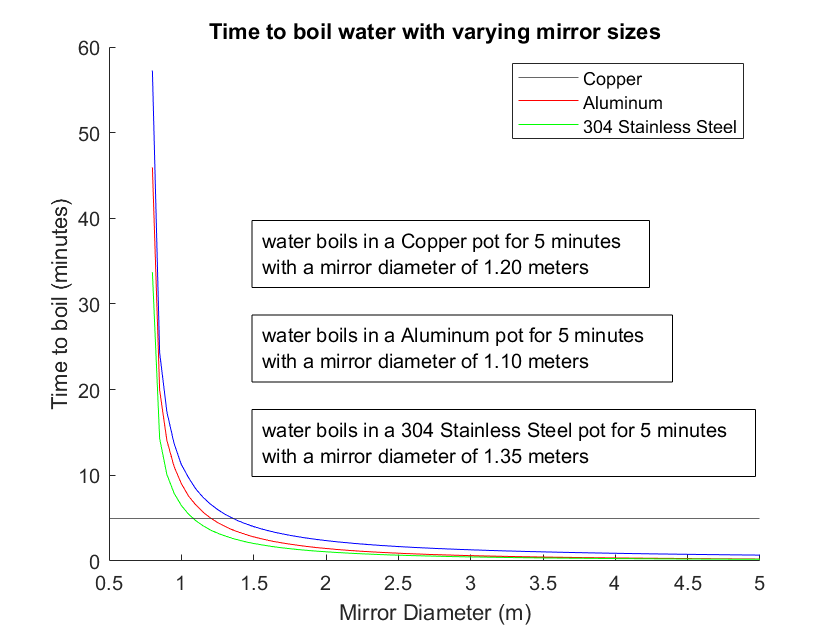

% materials = ["Copper", "Aluminum", "304 Stainless Steel"]; <- Already declared above no need
figure();
hold on

yline(5);
xlabel('Mirror Diameter (m)');
ylabel('Time to boil (minutes)');
title(sprintf("Time to boil water with varying mirror sizes"))
colors = {'r','g','b'};
colororder(colors);

diameterRange = .5:.05:5;
endTimes = zeros(length(diameterRange), 1);

dimensionIteration = 0;

for i = 1:length(materials)
    %subplot(1,length(materials),i) <-- is this needed?
    [time,waterTemp,potTemp,endTime] = single_diameter_v2(materials(i), 1);
    for diameterIndex = 1:length(diameterRange)
        [~,~,~,endTime] = single_diameter_v2(materials(i), diameterRange(diameterIndex));
        if endTime
            endTimes(diameterIndex) = endTime;
        else
            endTimes(diameterIndex) = NaN;
        end
    end
    
    % figure();
    
    plot(diameterRange, endTimes)
    [val, idx] = min(abs(endTimes-5));
    threshold = diameterRange(idx);
    
    dim = [.3 .55-dimensionIteration .1 .1];
    
    dimensionIteration = dimensionIteration + 0.15;
    
    txt = sprintf("water boils in a %s pot for 5 minutes \nwith a mirror diameter of %.2f meters", materials(i), threshold);
    annotation('textbox', dim ,'String', txt)
end

legend('Copper','Aluminum','304 Stainless Steel')

## **Interpretation:**

## **Works Cited: (to be formatted properly later)**

Miro Board Link: [https://miro.com/app/board/o9J_kg0-7nE=/](https://miro.com/app/board/o9J_kg0-7nE=/)

copper and aluminum properties: [https://www.periodic-table.org](https://www.periodic-table.org)

304 Stainless Steel properties: [https://www.aksteel.com/sites/default/files/2018-01/304304L201706_1.pdf](https://www.aksteel.com/sites/default/files/2018-01/304304L201706_1.pdf)

Link to Intro to Thermal Packet: 

Solar Insulation Calculator: [https://www.pveducation.org/pvcdrom/properties-of-sunlight/calculation-of-solar-insolation](https://www.pveducation.org/pvcdrom/properties-of-sunlight/calculation-of-solar-insolation)